# Quick Start Example: Accessing Neuropixels electrophysiology data from the Allen Brain Observatory

The Brain Observatory Toolbox represents the available electrophysiology ('ephys') data from the Allen Brain Observatory resource [1] as a set of Matlab `table` objects. These collectively contain the manifest of all available data, and are accessed through several `fetch...()` functions:

sessionTable = bot.fetchSessions('ephys');
probeTable = bot.fetchProbes();
channelTable = bot.fetchChannels();
unitTable = bot.fetchUnits();

The ephys data was obtained with Neuropixels neural probe technology [2].

The manifest contains [table arrays](https://www.mathworks.com/help/matlab/tables.html) of :

- experimental ephys *sessions *

- associated Neuropixels *probes, *for these sessions

- associated Neuropixels *channels, *for these probes

- inferred neuronal sources, known as *units*, extracted from these channel recordings

The Allen Brain Observatory resource contains dozens of ephys sessions, with recordings from hundreds of probes, capturing tens of thousands of neuronal units:

whos sessionTable probeTable channelTable unitTable

  Name                   Size                 Bytes  Class    Attributes

  channelTable      123224x33            1731501528  table              
  probeTable           332x26               4851244  table              
  sessionTable          58x18                913706  table              
  unitTable          40010x59             634557292  table              



Let's inspect the table of available experimental  sessions. The table variables (columns) contain the identifiers and other key metadata for each of the sessions (rows):

head(sessionTable)

ans = 8×18 table
    type     date_of_acquisition     fail_eye_tracking       id        isi_experiment_id    published_at    specimen_id        session_type           specimen      well_known_files    age_in_days    sex                      full_genotype                      has_nwb    unit_count    channel_count    probe_count    ephys_structure_acronyms
    _____    ____________________    _________________    _________    _________________    ____________    ___________    _____________________    ____________    ___________

Table [indexing operations](https://www.mathworks.com/help/matlab/matlab_prog/access-data-in-a-table.html) can be used to sub-select specific experimental sessions with attributes of interest, such as functional connectivity sessions with female subjects: 

sessionTable = sessionTable(sessionTable.session_type == "functional_connectivity",:);
sessionTable = sessionTable(sessionTable.sex == "F",:);
height(sessionTable)

ans = 8

The table can be used to create a session object array, which represents the underlying data for one or more of these sub-selected sessions. Each session object in the array contains sub-tables containing the identifiers and metadata for the associated channels and probes. Inspect the table of probes associated to the first sub-selected sessions:

session = bot.session(sessionTable(1,:));
probesTable = session.probes

probesTable = 6×26 table
    air_channel_index    ephys_session_id       id        lfp_sampling_rate    lfp_temporal_subsampling_factor       name       phase     sampling_rate    surface_channel_index    has_lfp_data    type     date_of_acquisition     fail_eye_tracking    isi_experiment_id    published_at    specimen_id         session_type            specimen      well_known_files    age_in_days    sex                       genotype                        has_nwb    unit_count    channel_count    ephys_structure_acronyms
    ________________

Given the high density of Neuropixels ephys probes, this single experimental session comprises data from thousands of channels: 

sum(probesTable.channel_count)

ans = 2232

The session object also contains a table representing the pre-computed inferred neuronal units which number in the hundreds:

unitsTable = session.units;
height(unitsTable)

ans = 700

Compute summary statistics and generate plots from these units' metadata, such as the firing rate: 

summary(unitsTable(:,"firing_rate"));

Variables:

    firing_rate: 700×1 double

        Values:

            Min       0.06027 
            Median     4.8539 
            Max        55.334 



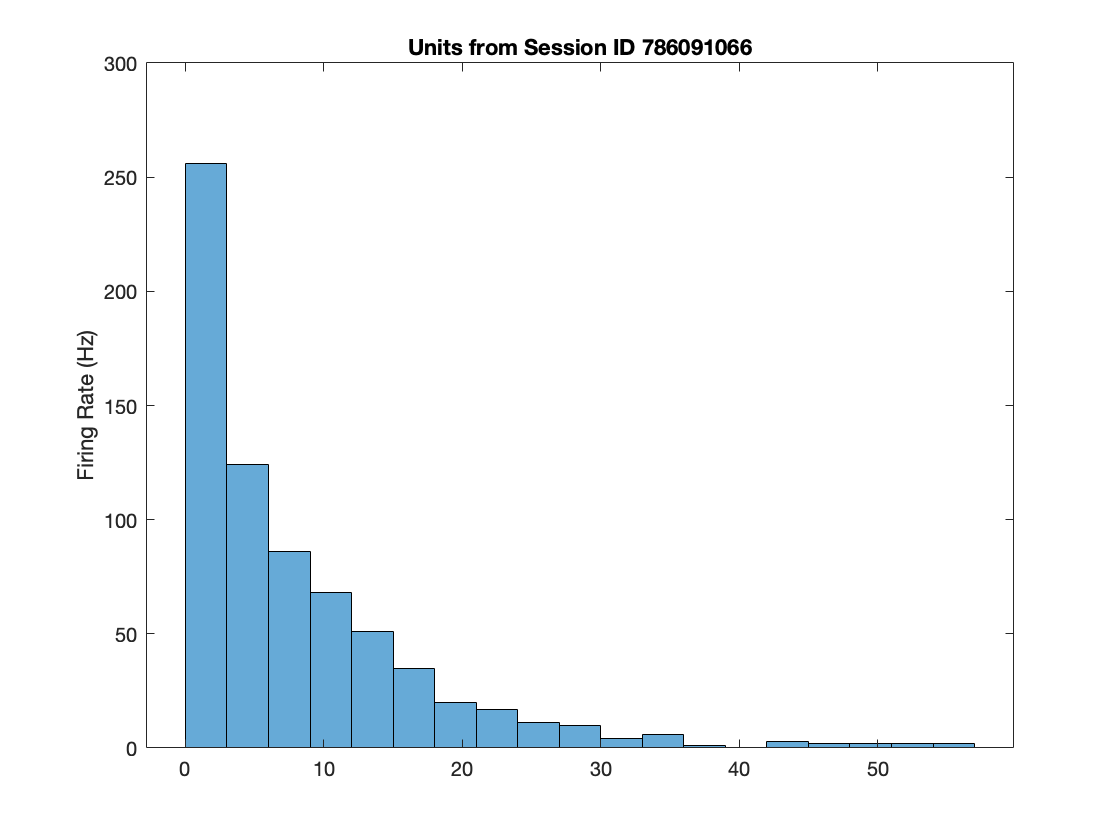

histogram(unitsTable.firing_rate);
ylabel('Firing Rate (Hz)');
title("Units from Session ID " + session.id);

High firing rate units (>40 Hz) can be observed in the tail of the distribution from this selected functional connectivity session with a female subject.

## References

[1] Copyright 2016 Allen Institute for Brain Science. Allen Brain Observatory. Available from: [https://portal.brain-map.org/explore/circuits/visual-coding-neuropixels](https://portal.brain-map.org/explore/circuits/visual-coding-neuropixels)

[2] Information about Neuropixels probes available at [https://neuropixels.org](https://neuropixels.org)